# Part 1

## Plot Spectral Sensitivty Functions

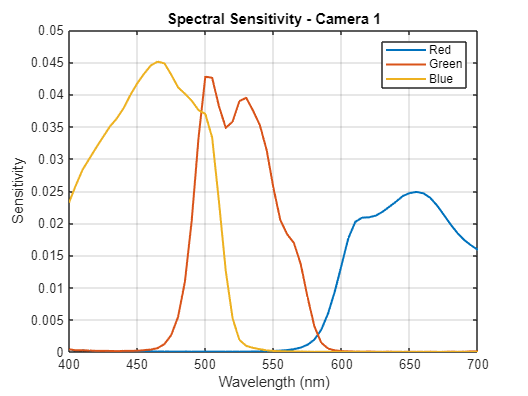

% Load data for spectral sensitivity functions and wavelengths
load('Ad.mat'); % Spectral sensitivity for Camera 1
load('Ad2.mat'); % Spectral sensitivity for Camera 2
load('illum.mat'); % Wavelength range

% Plot sensitivity functions for both cameras
figure;
plot(waverange, Ad, 'LineWidth', 1.5);
title('Spectral Sensitivity - Camera 1');
xlabel('Wavelength (nm)');
ylabel('Sensitivity');
legend('Red', 'Green', 'Blue');
grid on;

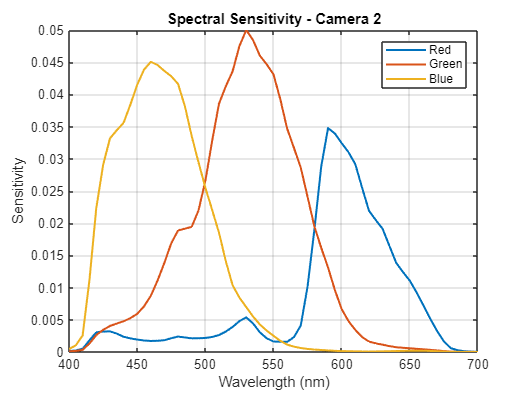


figure;
plot(waverange, Ad2, 'LineWidth', 1.5);
title('Spectral Sensitivity - Camera 2');
xlabel('Wavelength (nm)');
ylabel('Sensitivity');
legend('Red', 'Green', 'Blue');
grid on;

## Raw RGB outputs

% Load reflectance, illuminant, and sensitivity data
load('chips20.mat'); % Spectral reflectance data for 20 objects (20x61 matrix)
load('illum.mat'); % Illuminants (1x61 vectors for each illuminant)
load('Ad.mat'); % Spectral sensitivity for Camera 1 (61x3 matrix)
load('Ad2.mat'); % Spectral sensitivity for Camera 2 (61x3 matrix)

% Select D65 as the illuminant (1x61 vector)
illuminant = CIED65;

% Compute RGB raw outputs for Camera 1
RGB_raw_D65_cam1 = chips20 .* illuminant; % Elementwise multiplication (20x61)
RGB_raw_D65_cam1 = RGB_raw_D65_cam1 * Ad; % Matrix multiplication (20x3)

% Compute RGB raw outputs for Camera 2
RGB_raw_D65_cam2 = chips20 .* illuminant; % Elementwise multiplication (20x61)
RGB_raw_D65_cam2 = RGB_raw_D65_cam2 * Ad2; % Matrix multiplication (20x3)

% Display the results
disp('RGB Raw Outputs for Camera 1 under D65:');

RGB Raw Outputs for Camera 1 under D65:


disp(RGB_raw_D65_cam1);

    0.2979    0.3654    0.5056
    0.1397    0.1277    0.2314
    0.0408    0.0651    0.1183
    0.0711    0.0977    0.1715
    0.1003    0.3576    0.4496
    0.1137    0.2291    0.3414
    0.2697    0.2824    0.1179
    0.0345    0.0318    0.0527
    0.1561    0.1547    0.0481
    0.0201    0.0248    0.0368
    0.0972    0.0467    0.1289
    0.1110    0.0672    0.0886
    0.0737    0.0517    0.0931
    0.0584    0.1327    0.0656
    0.1226    0.2596    0.5293
    0.0787    0.0537    0.1410
    0.0700    0.2887    0.4728
    0.1151    0.0602    0.0561
    0.2861    0.3616    0.1974
    0.1512    0.2132    0.3133




disp('RGB Raw Outputs for Camera 2 under D65:');

RGB Raw Outputs for Camera 2 under D65:


disp(RGB_raw_D65_cam2);

    0.3125    0.5787    0.4609
    0.1413    0.2131    0.2049
    0.0462    0.1010    0.1052
    0.0783    0.1542    0.1527
    0.1557    0.5100    0.4109
    0.1381    0.3442    0.3091
    0.2619    0.4339    0.1244
    0.0354    0.0523    0.0471
    0.1689    0.2683    0.0561
    0.0216    0.0392    0.0331
    0.0769    0.0815    0.1111
    0.1082    0.1220    0.0799
    0.0704    0.0875    0.0824
    0.0805    0.2098    0.0684
    0.1458    0.3915    0.4734
    0.0686    0.0906    0.1223
    0.1078    0.4063    0.4297
    0.1088    0.1117    0.0527
    0.2935    0.5418    0.1978
    0.1666    0.3336    0.2829




% Save results
save('RGB_raw_D65_cam1.mat', 'RGB_raw_D65_cam1');
save('RGB_raw_D65_cam2.mat', 'RGB_raw_D65_cam2');


## Part 2

## Compute Normalization Factors

% Define a white spectrum (ones for all wavelengths)
white_spectrum = ones(1, 61);

% Compute normalization factors for Camera 1
norm_factors_cam1 = white_spectrum * Ad; % (1x61) * (61x3) = (1x3)

% Compute normalization factors for Camera 2
norm_factors_cam2 = white_spectrum * Ad2; % (1x61) * (61x3) = (1x3)

disp('Normalization factors for Camera 1:');

Normalization factors for Camera 1:


disp(norm_factors_cam1);

    0.4635    0.5646    0.8585




disp('Normalization factors for Camera 2:');

Normalization factors for Camera 2:


disp(norm_factors_cam2);

    0.4726    0.8747    0.7420



## Calibrate Raw RGB

% Normalize raw RGB data using normalization factors
RGB_cal_D65_cam1 = RGB_raw_D65_cam1 ./ norm_factors_cam1; % Elementwise division
RGB_cal_D65_cam2 = RGB_raw_D65_cam2 ./ norm_factors_cam2; % Elementwise division

% Save calibrated data
save('RGB_cal_D65_cam1.mat', 'RGB_cal_D65_cam1');
save('RGB_cal_D65_cam2.mat', 'RGB_cal_D65_cam2');



## Compare Illuminants D65 and A

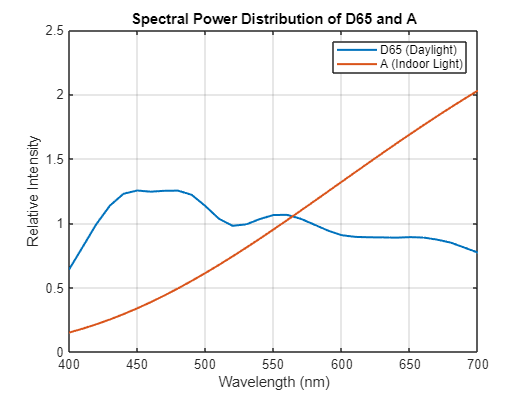

% Compare spectral power distributions of D65 and A
figure;
plot(waverange, CIED65, 'LineWidth', 1.5); hold on;
plot(waverange, CIEA, 'LineWidth', 1.5);
title('Spectral Power Distribution of D65 and A');
xlabel('Wavelength (nm)');
ylabel('Relative Intensity');
legend('D65 (Daylight)', 'A (Indoor Light)');
grid on;

## RGB output under A

% Compute raw RGB outputs for Camera 1 under Illuminant A
RGB_raw_A_cam1 = chips20 .* CIEA; % Elementwise multiplication (20x61)
RGB_raw_A_cam1 = RGB_raw_A_cam1 * Ad; % Matrix multiplication (20x3)

% Calibrate the raw data
RGB_cal_A_cam1 = RGB_raw_A_cam1 ./ norm_factors_cam1; % Elementwise division

% Save results
save('RGB_cal_A_cam1.mat', 'RGB_cal_A_cam1');


## White point normalization D65 & A

% Compute new normalization factors for D65 and A
norm_factors_D65 = CIED65 * Ad; % (1x61) * (61x3) = (1x3)
norm_factors_A = CIEA * Ad; % (1x61) * (61x3) = (1x3)

% Normalize raw RGB data for D65 and A
RGB_cal_D65_wp = RGB_raw_D65_cam1 ./ norm_factors_D65; % Elementwise division
RGB_cal_A_wp = RGB_raw_A_cam1 ./ norm_factors_A; % Elementwise division

% Save results
save('RGB_cal_D65_wp.mat', 'RGB_cal_D65_wp');
save('RGB_cal_A_wp.mat', 'RGB_cal_A_wp');



## Part 3

## Compute refrence XYZ

% Load color matching functions (CMFs)
load('xyz.mat'); % (61x3 matrix: columns for x, y, z)

% Compute normalization factor for Y=100 for a white reference
norm_factor = 100 / sum(CIED65 .* xyz(:, 2)');

% Compute XYZ reference values for the 20 surfaces under D65
XYZ_D65_ref = norm_factor * (chips20 .* CIED65) * xyz; % (20x61) * (61x3) = (20x3)

% Save reference XYZ values
save('XYZ_D65_ref.mat', 'XYZ_D65_ref');


## Matrix conversion sRGB

% Convert estimated XYZ to CIELAB
white_point = [95.047, 100.000, 108.883]; % Standard D65 white point

% Reference LAB values (split XYZ into X, Y, Z columns)
X_ref = XYZ_D65_ref(:, 1); % X column
Y_ref = XYZ_D65_ref(:, 2); % Y column
Z_ref = XYZ_D65_ref(:, 3); % Z column
[L_ref, a_ref, b_ref] = xyz2lab(X_ref, Y_ref, Z_ref); % Convert reference XYZ to LAB

% Estimated LAB values
X_est = XYZ_D65_est(:, 1); % X column
Y_est = XYZ_D65_est(:, 2); % Y column
Z_est = XYZ_D65_est(:, 3); % Z column
[L_est, a_est, b_est] = xyz2lab(X_est, Y_est, Z_est); % Convert estimated XYZ to LAB

% Compute ΔEab (Euclidean distance in LAB space)
delta_E = sqrt((L_ref - L_est).^2 + (a_ref - a_est).^2 + (b_ref - b_est).^2); % (20x1 vector)

% Compute mean and max ΔEab
mean_delta_E = mean(delta_E);
max_delta_E = max(delta_E);

% Display results
disp(['Mean ΔEab (sRGB Conversion): ', num2str(mean_delta_E)]);

Mean ΔEab (sRGB Conversion): 61.6108


disp(['Max ΔEab (sRGB Conversion): ', num2str(max_delta_E)]);

Max ΔEab (sRGB Conversion): 91.6435


## Compare camera snsitivty

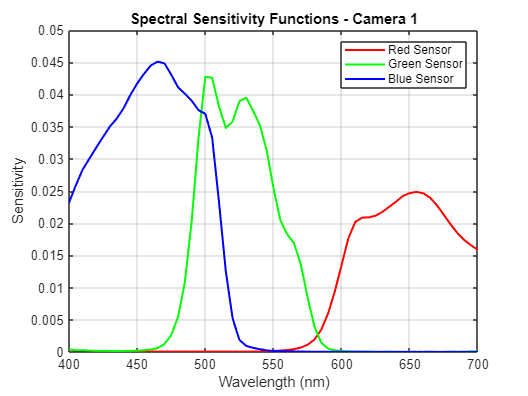

% Load necessary data
load('Ad.mat'); % Spectral sensitivity for Camera 1 (61x3 matrix)
load('xyz.mat'); % Color matching functions (61x3 matrix)
load('illum.mat'); % Wavelength range

% Plot Camera 1 sensitivity functions
figure;
plot(waverange, Ad(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(waverange, Ad(:, 2), 'g', 'LineWidth', 1.5);
plot(waverange, Ad(:, 3), 'b', 'LineWidth', 1.5);
title('Spectral Sensitivity Functions - Camera 1');
xlabel('Wavelength (nm)');
ylabel('Sensitivity');
legend('Red Sensor', 'Green Sensor', 'Blue Sensor');
grid on;

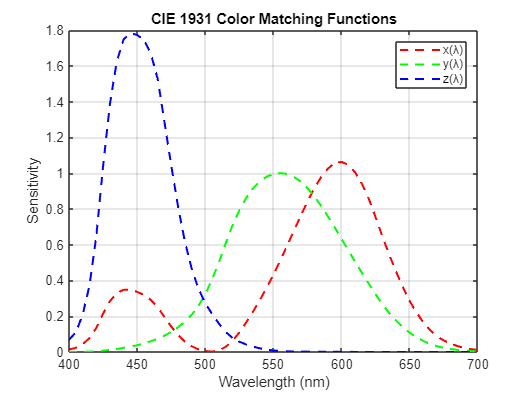


% Plot CMFs (standard observer)
figure;
plot(waverange, xyz(:, 1), '--r', 'LineWidth', 1.5); hold on;
plot(waverange, xyz(:, 2), '--g', 'LineWidth', 1.5);
plot(waverange, xyz(:, 3), '--b', 'LineWidth', 1.5);
title('CIE 1931 Color Matching Functions');
xlabel('Wavelength (nm)');
ylabel('Sensitivity');
legend('x(λ)', 'y(λ)', 'z(λ)');
grid on;

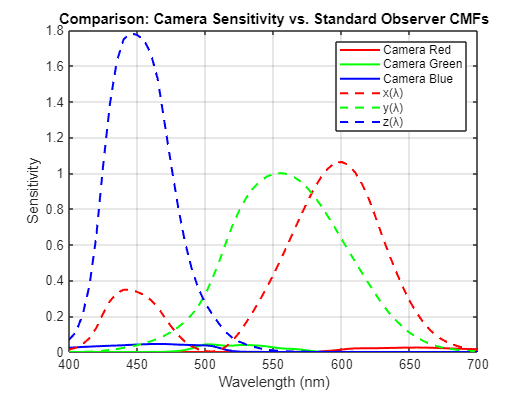


% Combine both plots for comparison
figure;
plot(waverange, Ad(:, 1), 'r', 'LineWidth', 1.5); hold on;
plot(waverange, Ad(:, 2), 'g', 'LineWidth', 1.5);
plot(waverange, Ad(:, 3), 'b', 'LineWidth', 1.5);
plot(waverange, xyz(:, 1), '--r', 'LineWidth', 1.5);
plot(waverange, xyz(:, 2), '--g', 'LineWidth', 1.5);
plot(waverange, xyz(:, 3), '--b', 'LineWidth', 1.5);
title('Comparison: Camera Sensitivity vs. Standard Observer CMFs');
xlabel('Wavelength (nm)');
ylabel('Sensitivity');
legend('Camera Red', 'Camera Green', 'Camera Blue', 'x(λ)', 'y(λ)', 'z(λ)');
grid on;

## Linear regression RGB to XYZ

% Load necessary data
load('RGB_cal_D65_cam1.mat'); % Calibrated RGB values for Camera 1 under D65
load('XYZ_D65_ref.mat'); % Reference XYZ values under D65

% Perform linear regression to compute the transformation matrix A
A = pinv(RGB_cal_D65_cam1) * XYZ_D65_ref; % (3x20) * (20x3) = (3x3)

% Estimate XYZ values using the regression matrix A
XYZ_D65_reg = RGB_cal_D65_cam1 * A; % (20x3) * (3x3) = (20x3)

% Convert estimated XYZ to CIELAB
white_point = [95.047, 100.000, 108.883]; % D65 white point
X_reg = XYZ_D65_reg(:, 1); % X column
Y_reg = XYZ_D65_reg(:, 2); % Y column
Z_reg = XYZ_D65_reg(:, 3); % Z column
[L_est_reg, a_est_reg, b_est_reg] = xyz2lab(X_reg, Y_reg, Z_reg); % Convert to LAB

% Convert reference XYZ to LAB for comparison
X_ref = XYZ_D65_ref(:, 1); % X column
Y_ref = XYZ_D65_ref(:, 2); % Y column
Z_ref = XYZ_D65_ref(:, 3); % Z column
[L_ref, a_ref, b_ref] = xyz2lab(X_ref, Y_ref, Z_ref); % Convert to LAB

% Compute ΔEab (color difference in LAB space)
delta_E_reg = sqrt((L_ref - L_est_reg).^2 + (a_ref - a_est_reg).^2 + (b_ref - b_est_reg).^2);

% Compute mean and max ΔEab
mean_delta_E_reg = mean(delta_E_reg);
max_delta_E_reg = max(delta_E_reg);

% Display results
disp(['Mean ΔEab (Regression): ', num2str(mean_delta_E_reg)]);

Mean ΔEab (Regression): 2.1977


disp(['Max ΔEab (Regression): ', num2str(max_delta_E_reg)]);

Max ΔEab (Regression): 5.8376



% Save the regression results
save('TransformationMatrix_A.mat', 'A');
save('XYZ_D65_reg.mat', 'XYZ_D65_reg');


## Polynomial Regression RGB to XYZ

% Load necessary data
load('RGB_cal_D65_cam1.mat'); % Calibrated RGB values for Camera 1 under D65 (20x3 matrix)
load('XYZ_D65_ref.mat'); % Reference XYZ values under D65 (20x3 matrix)

% Transpose inputs to match Optimize_poly and Polynomial_regression expectations
RGB_train = RGB_cal_D65_cam1'; % Transpose to 3x20
XYZ_train = XYZ_D65_ref'; % Transpose to 3x20

% Call Optimize_poly to compute the polynomial regression matrix
A_poly = Optimize_poly(RGB_train, XYZ_train); % (11x3 matrix)

% Use Polynomial_regression to estimate XYZ values
% Pass RGB in the required 3xT format
XYZ_D65_poly = Polynomial_regression(RGB_train, A_poly); % (3x20 matrix)

% Transpose the result back to T x 3 for further processing
XYZ_D65_poly = XYZ_D65_poly'; % Transpose to 20x3

% Convert estimated XYZ to CIELAB
white_point = [95.047, 100.000, 108.883]; % D65 white point
X_poly = XYZ_D65_poly(:, 1); % X column
Y_poly = XYZ_D65_poly(:, 2); % Y column
Z_poly = XYZ_D65_poly(:, 3); % Z column
[L_est_poly, a_est_poly, b_est_poly] = xyz2lab(X_poly, Y_poly, Z_poly); % Convert to LAB

% Convert reference XYZ to LAB for comparison
X_ref = XYZ_D65_ref(:, 1); % X column
Y_ref = XYZ_D65_ref(:, 2); % Y column
Z_ref = XYZ_D65_ref(:, 3); % Z column
[L_ref, a_ref, b_ref] = xyz2lab(X_ref, Y_ref, Z_ref); % Convert to LAB

% Compute ΔEab (color difference in LAB space)
delta_E_poly = sqrt((L_ref - L_est_poly).^2 + (a_ref - a_est_poly).^2 + (b_ref - b_est_poly).^2);

% Compute mean and max ΔEab
mean_delta_E_poly = mean(delta_E_poly);
max_delta_E_poly = max(delta_E_poly);

% Display results
disp(['Mean ΔEab (Polynomial Regression): ', num2str(mean_delta_E_poly)]);

Mean ΔEab (Polynomial Regression): 1.0238


disp(['Max ΔEab (Polynomial Regression): ', num2str(max_delta_E_poly)]);

Max ΔEab (Polynomial Regression): 3.1053



% Save polynomial regression results
save('A_poly.mat', 'A_poly');
save('XYZ_D65_poly.mat', 'XYZ_D65_poly');
